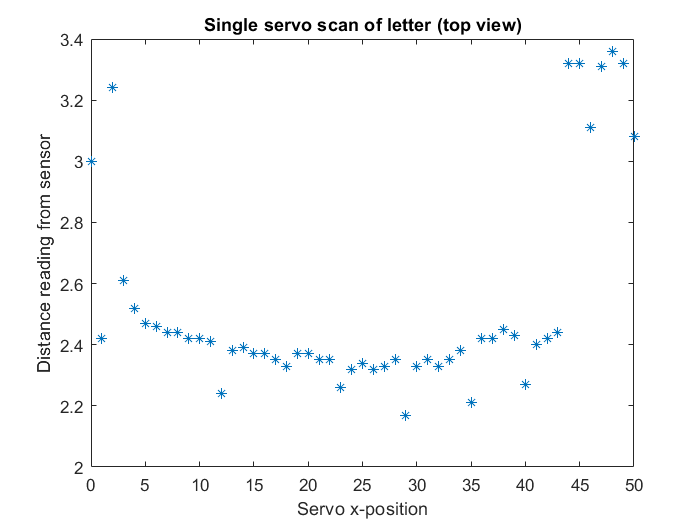

x2d = scan_read(1:51,1);
d2d = scan_read(1:51,3);
plot(x2d, d2d, "*")

xlabel("Servo x-position")
ylabel("Distance reading from sensor")
title("Single servo scan of letter (top view)")

load scan2clearbackground.mat
size(scan_read, 1) % check it has loaded correctly

ans = 2000

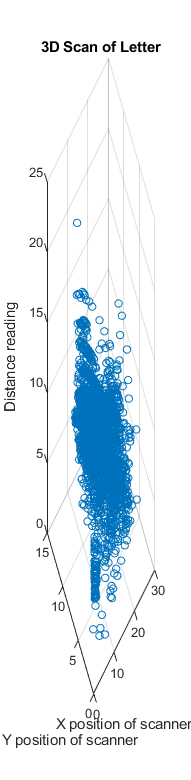

azimuth = deg2rad(scan_read(:,1)); % horizontal servo is azimuthal angle phi
elevation = deg2rad(scan_read(:,2)); % vertical servo is polar angle theta
r = scan_read(:,3); % distance reading from IR sensor is radial distance r

% convert from spherical to cartesian
[x, y, z] = sph2cart(azimuth,elevation,r);

% plot cartesian
scatter3(x, y, z, 20)
xlabel('X position of scanner')
ylabel('Y position of scanner')
zlabel('Distance reading')
title("3D Scan of Letter")